component intro

R1=50;
L4=0.5e-6;
C2=350e-12;
R3=680;
R5=1;
C6=350e-12;
R7=50;

Frequency and body plot definition

StartFreq=1;
NumDec=10;
NumPerDec=100;
Freq=zeros(NumPerDec*NumDec,1);
MagResponse=zeros(NumPerDec*NumDec,1);
PhasResponse=zeros(NumPerDec*NumDec,1);
Zimp=zeros(NumPerDec*NumDec,1);
Zphase=zeros(NumPerDec*NumDec,1);
Vin=1;

impedance

for i=1:NumDec*NumPerDec
    Freq(i)=StartFreq*10^(i/NumPerDec);
    s=1j*2*pi*Freq(i);
    Z1=R1;
    Z2=1/(s*C2);
    Z4=s*L4;
    Z3=R3;
    Z5=R5;
    Z6=1/(s*C6);
    Z7=R7;
    Z=[Z1+Z2+Z3,            -Z2,        -Z3;
            -Z2,    Z2+Z4+Z5+Z6,        -Z6;
            -Z3,            -Z6,    Z3+Z6+Z7];
    V=[Vin; 0; 0];
    I=(Z^(-1))*V;
    MagResponse(i)=abs(I(3)*Z7);
    PhasResponse(i)=phase(I(3)*Z7)*360/(2*pi);
    

input impedance

    Zimp(i)=Vin/I(1);
    Zphase(i)=angle(Zimp(i))*360/(2*pi);
end

Impedance plotting

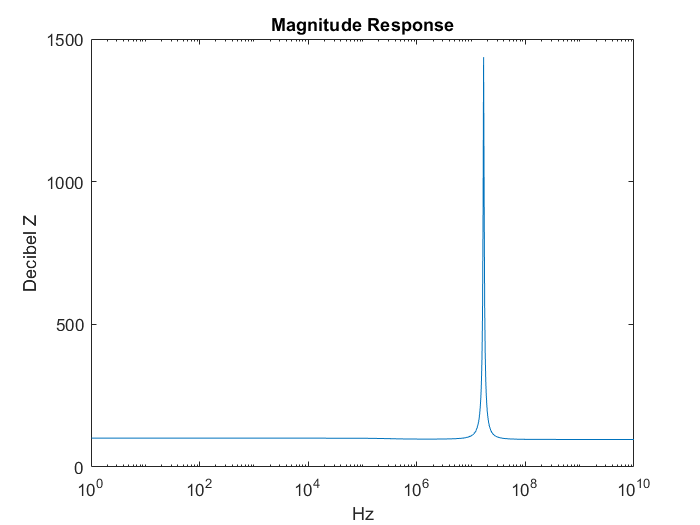

f1=figure;
semilogx(Freq,abs(Zimp))
title("Magnitude Response")
xlabel('Hz')
ylabel('Decibel Z')

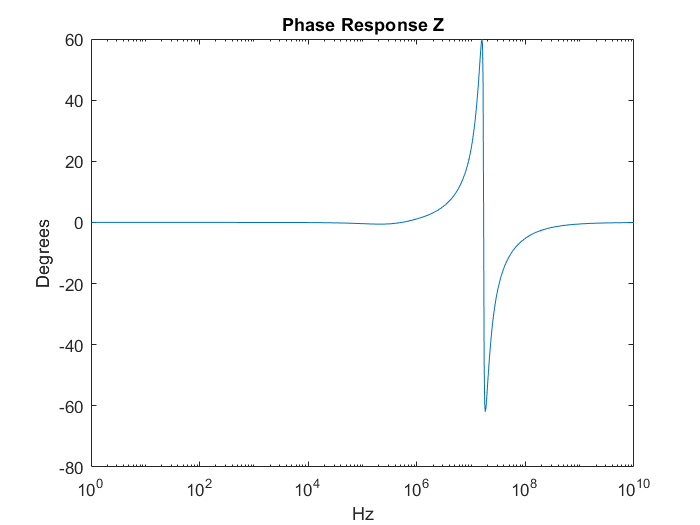

f2=figure;
semilogx(Freq,Zphase)
title("Phase Response Z")
xlabel('Hz')
ylabel('Degrees')

Plot magnitude

subplot(2,1,1);
HMag=semilogx(Freq,20*log10(MagResponse), 'color','k','linewidth',2);
set(gca,'FrontSize',12);
xlabel('Freq(Hz)');
ylabel('Response (dB)');
grid on;


PLot phase

subplot(2,1,2)
Hphase=semilogx(Freq,PhasResponse,'color','k','linewidth',2);
xlabel('Freq (Hz)');
ylabel('Phase (Degrees)');
ylim({-180 180});
grid on

x = logspace(-1,2,3)

x =     0.1000    3.1623  100.0000


y = x

y =     0.1000    3.1623  100.0000


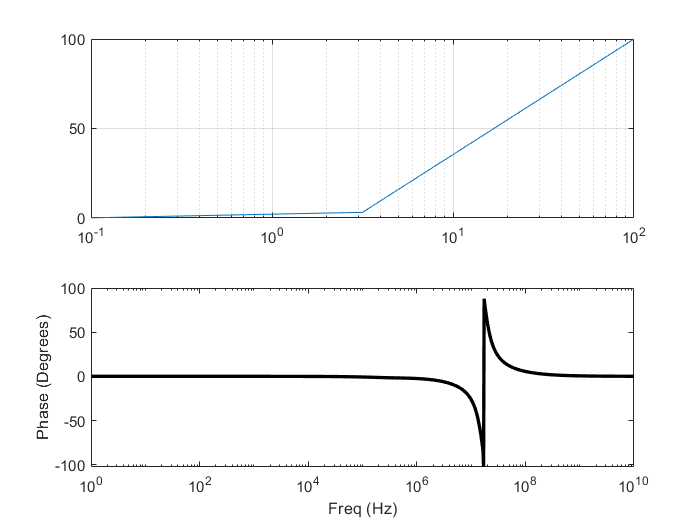

semilogx(x,y)
grid on